%linearity
clc;
close all;
clear all;
%n1 = -3:0.5:3;
%n2 = -1:0.5:5;

v=1:10;
a=1.5;
n1=a.^v;    %exponential Sequence 1
n2=a.^v;    %exponential Sequence 2

a1 = 2;
c1 = 5;
a2 = 3;
c2 = 6;

disp('Verfying linearity of y=mx');

Verfying linearity of y=mx


val1 = a1*x(n1) + a2*x(n2); 
val2 = x(a1*n1 + a2*n2);

disp(val1);

   15.0000   22.5000   33.7500   50.6250   75.9375  113.9063  170.8594  256.2891  384.4336  576.6504



disp(val2);

   15.0000   22.5000   33.7500   50.6250   75.9375  113.9063  170.8594  256.2891  384.4336  576.6504



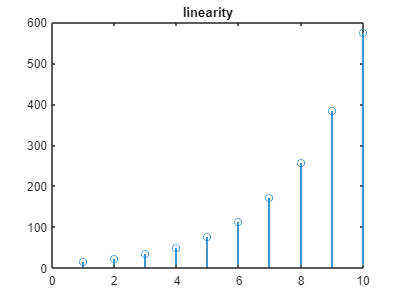

stem (val1);title('linearity');

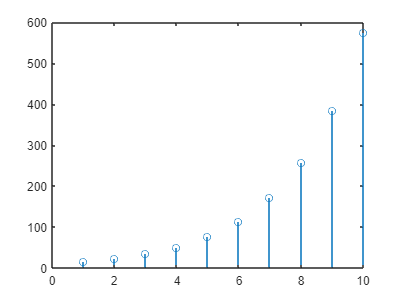

stem (val2);

clc;
disp('Verifying non-linearity of y=x(n)^2 function');

Verifying non-linearity of y=x(n)^2 function


m=x(n1);
n=x(n2);
o=x(n1+n2);
val3 = sqr(m) + sqr(n);
val4 = sqr(o);

disp(val3);

   1.0e+04 *

    0.0018    0.0040    0.0091    0.0205    0.0461    0.1038    0.2335    0.5255    1.1823    2.6602



disp(val4);

   1.0e+04 *

    0.0036    0.0081    0.0182    0.0410    0.0923    0.2076    0.4671    1.0509    2.3646    5.3204



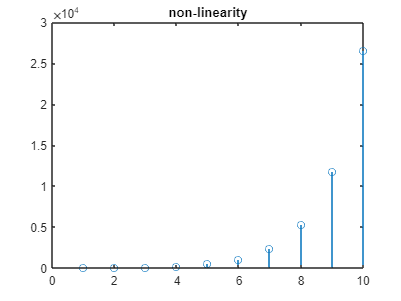

stem (val3);title('non-linearity');

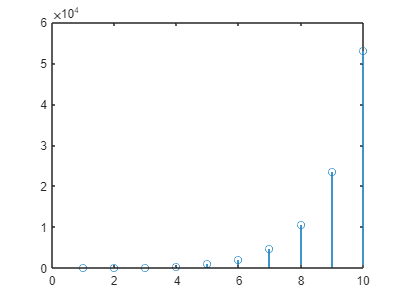

stem (val4);

%time invariance
clc;
clear all;
disp('Shifting Time');

Shifting Time


o=4;
x1=[1,4,9,16,25];
origin=x(o);
k=3;
y=[zeros(1,k) x1];
disp(x1);

     1     4     9    16    25



disp(y);

     0     0     0     1     4     9    16    25



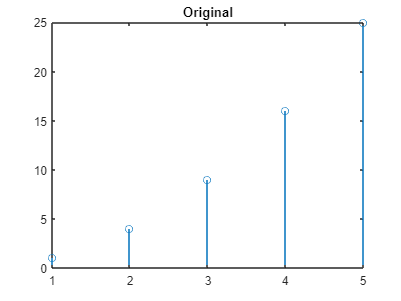

newOrigin=y(o);
stem(x1);
title("Original");

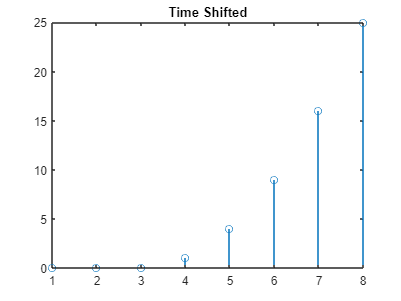

stem(y);
title("Time Shifted");

function square = sqr (x)
square = x.^2;
end

function yval = x(n)
yval = 2*n;
end